## Description des données

% Définition des limites du calcul 
x_min = -100;
x_max = 680;
y_min = -100;
y_max = 700;
theta_min = -pi/6;
theta_max = pi/6;

nb_x = 50;
nb_y = 50;
nb_theta = 5;
pas_x = (x_max-x_min)/(nb_x-1);
pas_y = (y_max-y_min)/(nb_y-1);
pas_th = (theta_max-theta_min)/(nb_theta-1);

## Génération des données

gen_data = true % Génération des données

gen_data = logical
   1


if gen_data == true
    les_x = [];
    les_y = [];
    les_theta = [];
    les_positions = [];
    les_bg = [];
    les_bd = [];
    les_hg = [];
    les_hd = [];
    
    x=x_min;
    y=y_min;
    th=theta_min;
    idx = 1;
    
    data_X = [];
    data_Y = []
    for i = 1:nb_x
        i
        y = y_min;
        for j = 1:nb_y
            th = theta_min;
            for k = 1:nb_theta
                les_x(end+1) = x;
                les_y(end+1) = y;
                les_theta(end+1) = th;
                
                [bg,phi] = get_L_phi(x,y,th,"BG");
                [bd,phi] = get_L_phi(x,y,th,"BD");
                [hg,phi] = get_L_phi(x,y,th,"HG");
                [hd,phi] = get_L_phi(x,y,th,"HD");
                les_bg(end+1) = bg;
                les_bd(end+1) = bd;
                les_hg(end+1) = hg;
                les_hd(end+1) = hd;
                les_positions(idx,1) = x;
                les_positions(idx,2) = y;
                les_positions(idx,3) = th;
    
          
                data_X(idx,1) = bg; 
                data_X(idx,2) = bd;
                data_X(idx,3) = hg;
                data_X(idx,4) = hd;
    
                data_Y(idx,1) = x; 
                data_Y(idx,2) = y;
                data_Y(idx,3) = th;
    
    
                idx = idx+1 ;
                th = th+pas_th;
            end
            y = y+ pas_y;
        end
        x = x + pas_x;
    end
    
    data_NN = table(transpose(les_bg),transpose(les_bd),transpose(les_hg),transpose(les_hd),les_positions, ...
        'VariableNames',["Les_BG","Les_BD","Les_HG","Les_HD","XM_YM_ThM"]) ;
    
    save('file.mat',"data_NN");
end


data_Y =

     []



i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

## Entrainement du réseau


% Normalisation des données
X = (data_X - mean(data_X)) ./ std(data_X);
y = (data_Y - mean(data_Y)) ./ std(data_Y);


cv = cvpartition(size(X,1),'HoldOut',0.3);
idx = cv.test;

X_train = X(~idx,:);
X_test = X(idx,:);

Y_train = y(~idx,:);
Y_test = y(idx,:);

% Statistiques utilisées pour la normalisation
mean_X = mean(data_X);
std_X = std(data_X);
mean_y = mean(data_Y);
std_y = std(data_Y);


% couches = [
%     featureInputLayer(size(X_train, 2))     % Couche d'entrée correspondant à la taille des caractéristiques
%     fullyConnectedLayer(64)                 % Couche cachée avec 20 neurones
%     reluLayer                               % Activation ReLU
%     fullyConnectedLayer(64)                 % Couche cachée avec 20 neurones
%     reluLayer                               % Activation ReLU
%     fullyConnectedLayer(size(Y_train, 2))   % Couche de sortie avec le bon nombre de classes
%     regressionLayer ]                           % Fonction d'activation softmax pour classification
% 
% 
% 
% 
% % Options d'entraînement
% options = trainingOptions("adam", ...
%     "MaxEpochs", 100, ...
%     "MiniBatchSize", 32, ...
%     "InitialLearnRate", 0.01, ...
%     "Verbose", true, ...
%     "Plots", "training-progress", ...
%     "ValidationData", {X_test, Y_test}, ...
%     "ValidationFrequency", 30);


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:00        0.001                            1.1033
            1        1       00:00:00        0.001          1.0385                  
           30        1       00:00:03        0.001         0.47695           0.40373
           50        1       00:00:03        0.001         0.36093                  
           60        1       00:00:04        0.001          0.3631           0.34067
           90        1       00:00:05        0.001         0.36184           0.32764
          100        1       00:00:05        0.001         0.27638                  
          120        1       00:00:06        0.001          0.2879           0.31805
          150        1       00:00:06        0.001          0.3326           0.30542
          180        1       00:00:07        0.001         0.2644

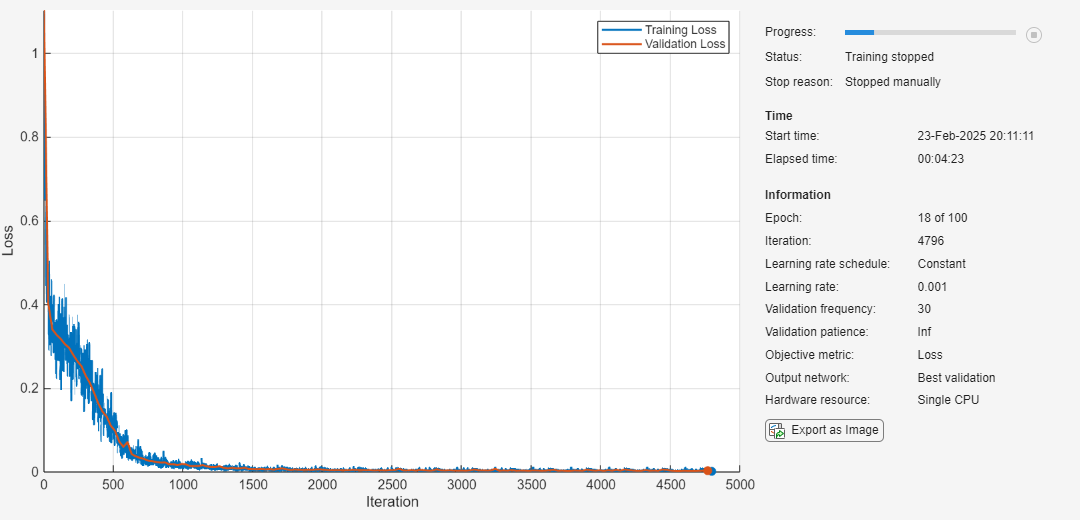

% Définition des couches
layers = [
    featureInputLayer(size(X_train, 2))
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(3)
    ];

% Options d'entraînement
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'ValidationData', {X_test, Y_test}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Entraînement du réseau
%net = trainNetwork(X_train, Y_train, layers, options);
net = trainnet(X_train, Y_train, layers,"mse", options);


y_pred(50,: ).* std_y + mean_y

Index in position 1 exceeds array bounds. Index must not exceed 1.

Y_test(50,:).* std_y + mean_y





% Prédiction sur les données de test
y_pred = predict(net, X_test);

% Évaluation des performances : Erreur quadratique moyenne (MSE)
mse = mean((y_pred - Y_test).^2);
fprintf('Erreur quadratique moyenne (MSE) : %.4f\n', mse);

% Évaluation avec le coefficient de détermination R²
ss_tot = sum((Y_test - mean(Y_test)).^2);
ss_res = sum((Y_test - y_pred).^2);
r2 = 1 - (ss_res / ss_tot);
fprintf('Coefficient de détermination (R²) : %.4f\n', r2);

% for i =1:length(les_xm)
%     [bg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BG");
%     [bd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BD");
%     [hg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HG");
%     [hd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HD");
%  les_bg(end+1) = bg;
%     les_bd(end+1) = bd;
%     les_hg(end+1) = hg;
%     les_hd(end+1) = hd;
% end

a = [les_bg(1), les_bd(1), les_hg(1),les_hd(1)];
xxx = X_train(1,:);
yyy = Y_train(1,:)
y_pred = predict(net, xxx)